# Experiment 3: HOG + SVM (Bounding Box)

## Clean environment

close all;
clear variables;
clc;

## Set folder path

folder = "C:\Users\u3253992\workspace\computer-vision\assignment_1\u3253992_assignment_1\data\CUB_200_2011_Subset20classes\";

## Load dataset

[trainingImageNames, validationImageNames, testImageNames, classNames, imageClassLabels, boundingBoxes] = loadDataset(folder, true);

Reading bounding box data


## Create datastores

disp('Training set class distribution:');

Training set class distribution:


trainingImageDS = createImageDatastore(trainingImageNames, folder, true, boundingBoxes);

    Label    Count
    _____    _____

     001      36  
     002      36  
     003      35  
     004      36  
     005      26  
     006      25  
     007      30  
     008      29  
     009      35  
     010      36  
     011      36  
     012      34  
     013      36  
     014      36  
     015      35  
     016      35  
     017      34  
     018      26  
     019      35  
     020      35  




disp('Validation set class distribution:');

Validation set class distribution:


validationImageDS = createImageDatastore(validationImageNames, folder, true, boundingBoxes);

    Label    Count
    _____    _____

     001       6  
     002      12  
     003      12  
     004      12  
     005       9  
     006       8  
     007      12  
     008      10  
     009      12  
     010      12  
     011      12  
     012      11  
     013      12  
     014      12  
     015      12  
     016      12  
     017      12  
     018      10  
     019      12  
     020      12  




disp('Test set class distribution:');

Test set class distribution:


testImageDS = createImageDatastore(testImageNames, folder, true, boundingBoxes);

    Label    Count
    _____    _____

     001      12  
     002      12  
     003      11  
     004      12  
     005       9  
     006       8  
     007      12  
     008       9  
     009      12  
     010      12  
     011      12  
     012      11  
     013      12  
     014      12  
     015      11  
     016      11  
     017      11  
     018       9  
     019      12  
     020      12  



## Resize image datastores and combine them with the labels

targetSize = [128 128]

targetSize =    128   128


trainCDS = resizeCombineDatastore(trainingImageDS, targetSize);
valCDS = resizeCombineDatastore(validationImageDS, targetSize);
testCDS = resizeCombineDatastore(testImageDS, targetSize);

## Show images

cellSize = [16 16]

cellSize =     16    16


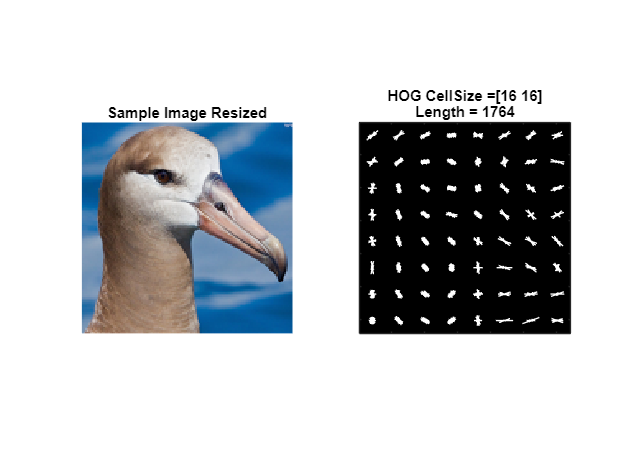

hogFeatureSize = 1764

hogFeatureSize = showImageFeatures(trainCDS, true, cellSize)

disp("HOG feature size is " + hogFeatureSize)

HOG feature size is 1764


## Extract HOG Features

trainFeatures = extractHOGFeaturesFromDatastore(trainCDS, hogFeatureSize, cellSize)

trainFeatures = 666×1764 single matrix
    0.0295    0.0151    0.0145    0.0178    0.0890    0.1565    0.2060    0.1127    0.0354    0.0470    0.0277    0.0363    0.0632    0.2852    0.2841    0.1465    0.1656    0.0768    0.0488    0.0412    0.0340    0.0498    0.0738    0.2852    0.2852    0.2806    0.0946    0.1356    0.0944    0.1106    0.1374    0.2852    0.2852    0.2852    0.2852    0.1924    0.0476    0.0318    0.0357    0.0648    0.2422    0.2206    0.1061    0.1595    0.0820    0.1298    0.0681    0.0410    0.0473    0.2422
    0.0294    0.0111    0.0199    0.0021    0.0308    0.0041    0.0215    0.0112    0.0293    0.0161    0.0080    0.0142    0.0019    0.0394    0.0051    0.0290    0.0112    0.0159    0.3929    0.3929    0.3929    0.3493    0.1952    0.0602    0.0676    0.2361    0.3929    0.0627    0.1836    0.3317    0.0303    0.0379    0.0073    0.0235    0.0102    0.0239    0.0335    0.0170    0.0312    0.0601    0.4523    0.0449    0.0621    0.0250    0.0332    0.0152

testFeatures = extractHOGFeaturesFromDatastore(testCDS, hogFeatureSize, cellSize)

testFeatures = 222×1764 single matrix
    0.1999    0.3267    0.3209    0.1222    0.1638    0.1201    0.0696    0.0537    0.0745    0.0805    0.1936    0.1021    0.0839    0.2068    0.1843    0.1094    0.0435    0.0400    0.1624    0.3267    0.3267    0.1200    0.0852    0.0514    0.0437    0.0433    0.0500    0.1131    0.3267    0.3267    0.1105    0.0729    0.0590    0.0521    0.0501    0.0671    0.0366    0.1494    0.1103    0.0951    0.2380    0.2228    0.1440    0.0478    0.0392    0.0157    0.0199    0.0340    0.1149    0.2726
    0.0260    0.0203    0.0165    0.0225    0.0733    0.2775    0.3419    0.2388    0.0346    0.0232    0.0162    0.0167    0.0296    0.0659    0.2728    0.3419    0.1439    0.0203    0.0206    0.0274    0.0228    0.1834    0.3419    0.3419    0.3419    0.2708    0.0475    0.0209    0.0209    0.0167    0.0202    0.0482    0.1277    0.1884    0.0615    0.0279    0.1227    0.0913    0.0826    0.1323    0.2502    0.3334    0.3334    0.3093    0.1094    0.1078 

## Enables GPU

[device, useGPU] = enableGPU();

✅ GPU found and ready:
  CUDADevice with properties:

                 Name: 'NVIDIA GeForce RTX 3070'
                Index: 1 (of 1)
    ComputeCapability: '8.6'
          DriverModel: 'WDDM'
          TotalMemory: 8589410304 (8.59 GB)
      AvailableMemory: 7443034112 (7.44 GB)
      DeviceAvailable: true
       DeviceSelected: true

  Show 

## Train classifier

SVMClassifier = trainSVMClassifier(trainFeatures, trainingImageDS.Labels);

## Evaluate

[accuracy, predictions] = evaluateClassifier(SVMClassifier, testFeatures, testImageDS.Labels);

[trainAccuracy, trainPredictions] = evaluateClassifier(SVMClassifier, trainFeatures, trainingImageDS.Labels);

disp("Train Accuracy = "+string(round(trainAccuracy*100, 1)))

Train Accuracy = 100


disp("Test Accuracy = "+string(round(accuracy*100, 1)))

Test Accuracy = 29.3


## Plot confusion matrix

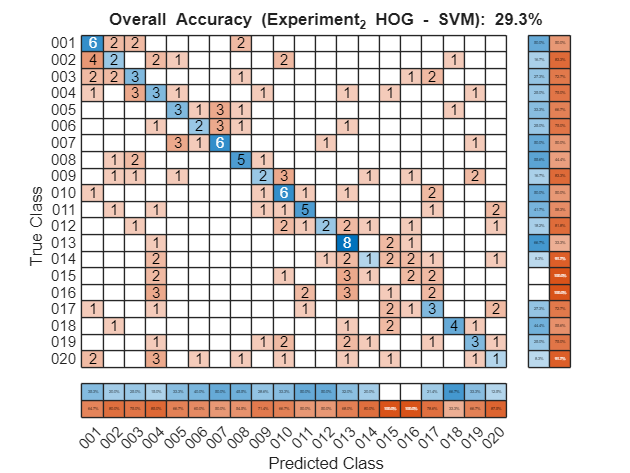

Classwise Recognition Rates:
   50.0000
   16.7000
   27.3000
   25.0000
   33.3000
   25.0000
   50.0000
   55.6000
   16.7000
   50.0000
   41.7000
   18.2000
   66.7000
    8.3000
         0
         0
   27.3000
   44.4000
   25.0000
    8.3000



plotConfusionMatrix(testImageDS.Labels, predictions, "Overall Accuracy (Experiment_2 HOG - SVM): " + string(round(accuracy*100, 1)) + "%");